%% Clear temporary variables
clear variables

# Analysis of a Synthetic Random Field with Rank Asymmetry

This section is identical to the E3A_DirectionalAsymmetry.mlx, with the only change being the replacement of the image with one that shows rank asymmetry. We also briefly illustrate how the field is generated.

## Model simulation

We model a field using the methodology proposed by Bardossy and Horning (2023). We generate a series of Gaussian random fields, transitioning from short-range spatial structures (15 pixels) with a nugget effect of 10%, to long-range structures (120 pixels) without a nugget effect. The same random seed and an exponential covariance function are used throughout the process. A threshold function is then applied to transform these fields into a non-Gaussian field. This approach relies on a continuous deformation of fields, each with distinct Gaussian spatial dependencies.

This script analyzes a synthetic asymmetry field by loading pre-generated data, visualizing rank asymmetry fields, and displaying various realizations of the asymmetry field. The visualizations help interpret the properties of the asymmetry field and its family.

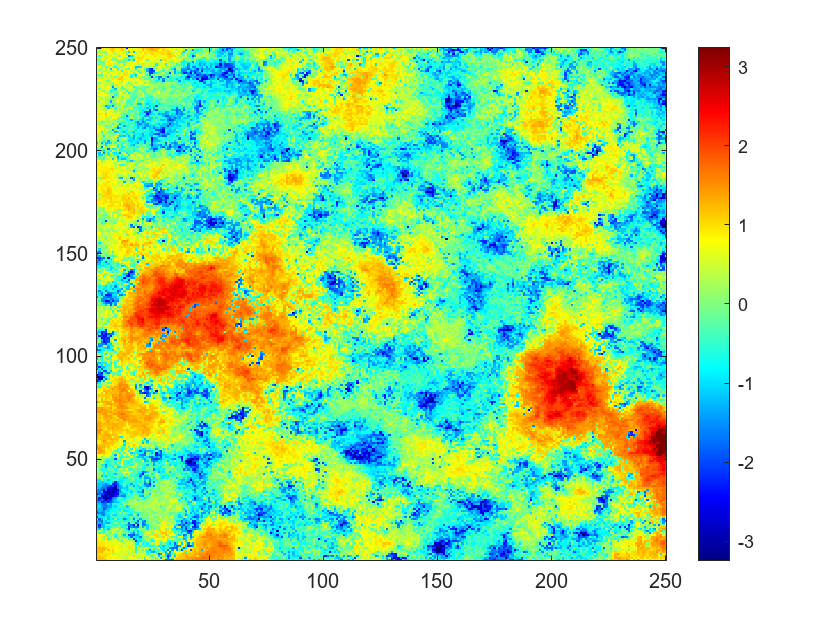

nx = 250;  % Number of grid points in the x-direction
ny = 250;  % Number of grid points in the y-direction
x0 = grille2(1, nx, 1, 1, ny, 1);  % Generate spatial grid

load("E3 - SyntheticAsymmetry/Synthetic_assymetric_field_c0.mat")  % Load synthetic asymmetry data

Z = [Z_Ass, Z_familly(:, 51)];  % Combine asymmetry data

%% Rank asymmetry field
figure(1)
imagesc(reshape(Z(:, 1), [nx ny]));  % Reshape and display the first rank asymmetry field
colorbar();  % Add colorbar
clim([-3.25 3.25])  % Set color limits
colormap 'jet'  % Set colormap to 'jet'
set(gca, 'YDir', 'normal')  % Set the y-axis direction to normal

## **Ensemble of the family used to generate the rank asymmetry field**

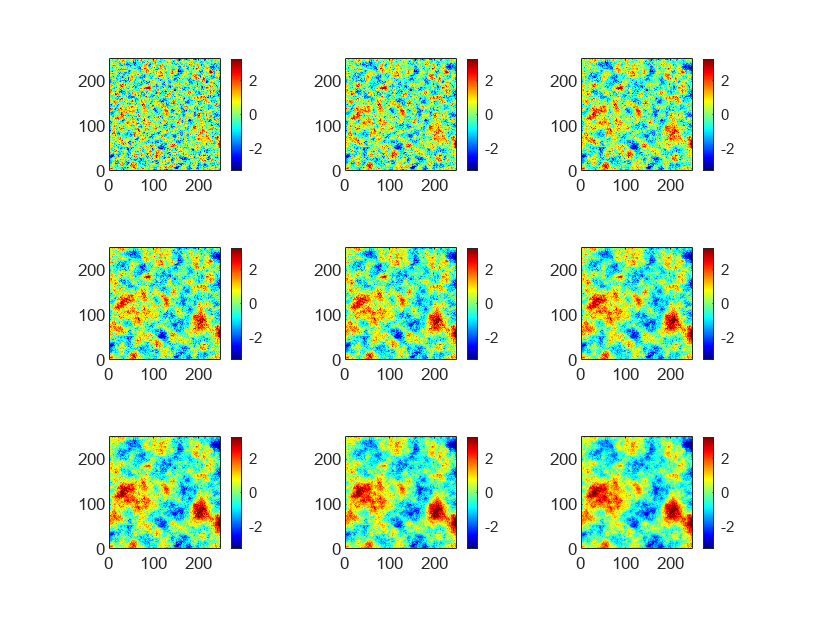

figure(3)
a = 0;  % Initialize counter
for i = round(1:(size(Z_familly, 2) - 1) / 9 : size(Z_familly, 2) - 1)
    a = a + 1;  % Increment counter
    subplot(3, 3, a)  % Create subplot
    imagesc(reshape(Z_familly(:, i), [nx ny]))  % Reshape and display the field
    colorbar();  % Add colorbar
    clim([-3.25 3.25])  % Set color limits
    colormap 'jet'  % Set colormap to 'jet'
    axis equal  % Set equal axis scaling
    xlim([0 nx]);  % Set x-axis limits
    ylim([0 ny]);  % Set y-axis limits
    set(gca, 'YDir', 'normal')  % Set the y-axis direction to normal
end

## **Compute the variogram**

This section computes the variogram of the synthetic asymmetry field. The data is set as non-categorical with `categ = 0`, and visualization is enabled by setting `display = 1`. The operation for variogram computation is defined with `icode = 1`, and the variogram is calculated using the `GeoStatFFT` function.

Next, 100 random fields are simulated with the `fftma` function. For each realization, the variogram is computed again using `GeoStatFFT`, and the results are stored in `gh1`.

The results are visualized in Figure 31, where each realization's variogram values are plotted as light gray lines. The mean variogram is shown as a bold black line, along with dashed lines representing the 5th and 95th percentiles.

Vertical and horizontal variogram results are displayed in green and red, respectively. The plot includes labels for the x-axis (Distance) and y-axis (Rank asymmetry value) and features a legend for clarity. The font size and axis limits are adjusted for better readability.

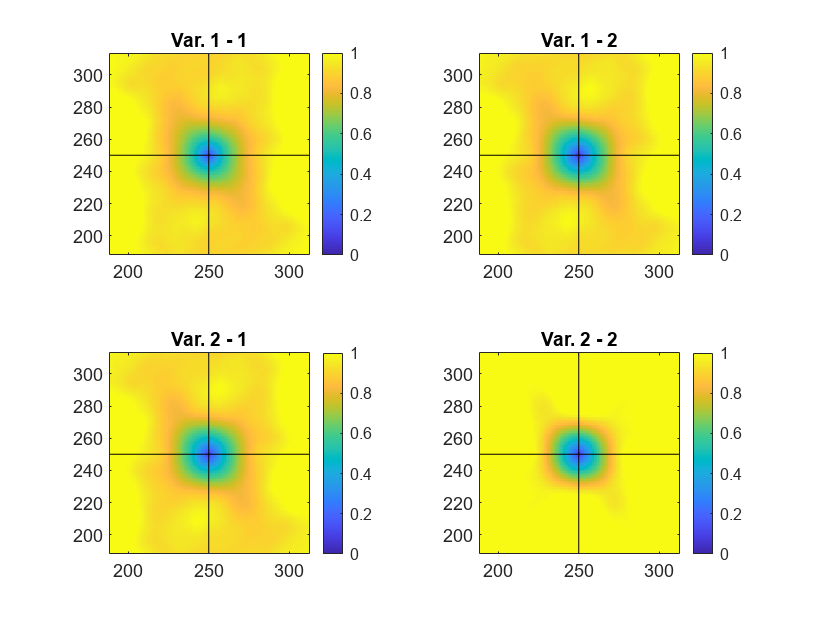

categ = 0; % Specify that the data is not categorical
display = 1; % Set display flag to true for visualization
rank = 0; % Set rank for GeoStatFFT
icode = 1; % Set code for variogram computation
[gh, ~] = GeoStatFFT(x0, Z, icode, categ, display, rank); % Compute bivariate asymmetry

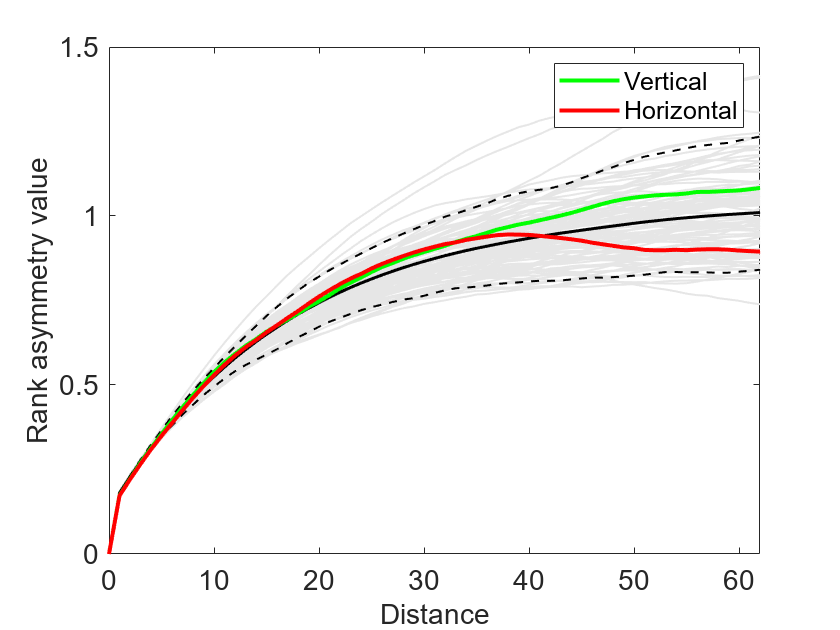


% Simulation of random fields
[z]=fftma([1 0 0 0 0 0 0 ; 2 50/3 50/3 50/3 0 0 0],[0.13 ; 0.87],45124241,100,nx,1,ny,1);
for i =1:100
    gh1{i} = GeoStatFFT(x0,z(:,i),icode);
end

% Plot the variogram results
figure(31)
for i = 1:100
    plot(0:length(gh1{i}{1,1}(nx:end,ny))-1, gh1{i}{1,1}(nx:end,ny), 'color', [0.9 0.9 0.9], 'LineWidth', 1) % Plot each realization
    hold on
    gmean(:, i) = gh1{i}{1,1}(nx:end, ny); % Store mean values for each realization
end
plot(0:length(mean(gmean, 2))-1, mean(gmean, 2), '-k', 'LineWidth', 1.5) % Plot mean
hold on
plot(0:length(quantile(gmean, 0.05, 2))-1, quantile(gmean, 0.05, 2), '--k', 'LineWidth', 1) % Plot 5th percentile
hold on
plot(0:length(quantile(gmean, 0.95, 2))-1, quantile(gmean, 0.95, 2), '--k', 'LineWidth', 1) % Plot 95th percentile
hold on
h1 = plot(0:length(gh{1,1}(nx:end, ny))-1, gh{1,1}(nx:end, ny), '-g', 'LineWidth', 2); % Plot vertical bivariate asymmetry
hold on
h2 = plot(0:length(gh{1,1}(nx, ny:end))-1, gh{1,1}(nx, ny:end), '-r', 'LineWidth', 2); % Plot horizontal bivariate asymmetry
legend([h1 h2], {'Vertical', 'Horizontal'}) % Add legend
xlabel('Distance') % Label x-axis
ylabel('Rank asymmetry value') % Label y-axis
fontsize(gca, 14, 'points'); % Adjust font size
xlim([0 floor(nx/4)]);

## **Compute the directional asymmetry**

This section computes the directional asymmetry of a synthetic asymmetry field. The data is classified as non-categorical by setting `categ = 0`, and visualization is enabled with `display = 1`. The field is transformed into rank values by specifying `rank = 1`, while the operation for calculating directional asymmetry is defined with `icode = 8`.

Next, 100 Gaussian random fields (GRFs) with the same variogram as the image are simulated using the `fftma` function. For each realization, the directional asymmetry is recalculated with `GeoStatFFT`, and the results are stored in `gh1`.

The results are visualized in Figure 51, where each GRF realization's asymmetry values are plotted as light gray lines. The mean asymmetry is represented by a bold black line, along with dashed lines for the 5th and 95th percentiles.

Finally, vertical and horizontal asymmetry results are displayed in green and red, respectively. The plot includes labels for the x-axis (Distance) and y-axis (Directional asymmetry value), along with a legend. Axis limits and minor ticks are adjusted to enhance readability.

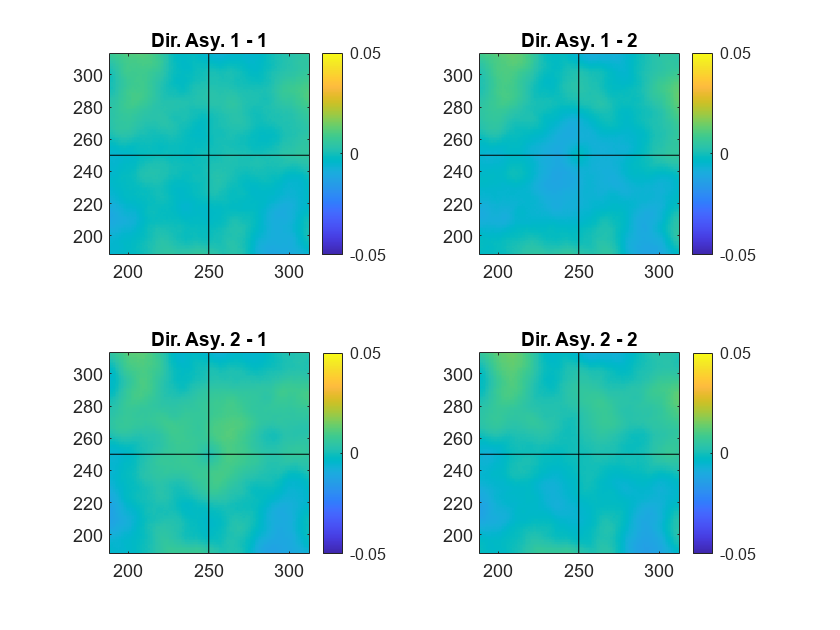

categ = 0; % Specify that the data is not categorical
display = 1; % Set display flag to true for visualization
rank = 1; % Set rank for GeoStatFFT
icode = 8; % Set code for directional asymmetry computation
figure(84512)
[gh, ~] = GeoStatFFT(x0, Z, icode, categ, display, rank); % Compute directional asymmetry

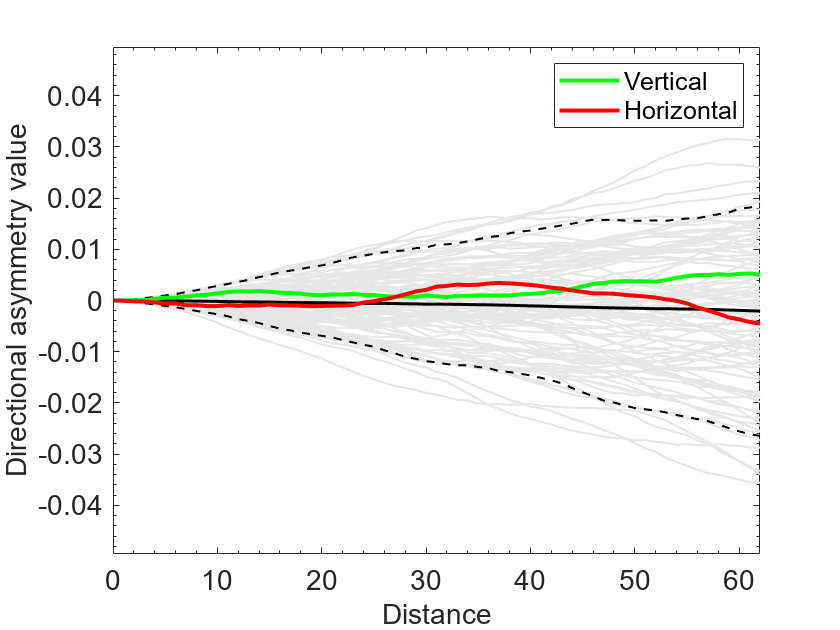

categ = 0; % Specify that the data is not categorical
display = 0; % Set display flag to true for visualization
rank = 1; % Set rank for GeoStatFFT
%% Simulation of random fields for directional asymmetry
[z]=fftma([1 0 0 0 0 0 0 ; 2 50/3 50/3 50/3 0 0 0],[0.13 ; 0.87],45124241,100,nx,1,ny,1);
for i =1:100
    gh1{i} = GeoStatFFT(x0,z(:,i),icode, categ, display, rank);
end

% Plot the directional asymmetry results
figure(51)
for i = 1:100
    plot(0:length(gh1{i}{1,1}(nx:end, ny))-1, gh1{i}{1,1}(nx:end, ny), 'color', [0.9 0.9 0.9], 'LineWidth', 1) % Plot each realization
    hold on
    gmean(:, i) = gh1{i}{1,1}(nx:end, ny); % Store mean values for each realization
end
plot(0:length(mean(gmean, 2))-1, mean(gmean, 2), '-k', 'LineWidth', 1.5) % Plot mean
hold on
plot(0:length(quantile(gmean, 0.05, 2))-1, quantile(gmean, 0.05, 2), '--k', 'LineWidth', 1) % Plot 5th percentile
hold on
plot(0:length(quantile(gmean, 0.95, 2))-1, quantile(gmean, 0.95, 2), '--k', 'LineWidth', 1) % Plot 95th percentile
hold on
h1 = plot(0:length(gh{1,1}(nx:end, ny))-1, gh{1,1}(nx:end, ny), '-g', 'LineWidth', 2); % Plot vertical asymmetry
hold on
h2 = plot(0:length(gh{1,1}(nx, ny:end))-1, gh{1,1}(nx, ny:end), '-r', 'LineWidth', 2); % Plot horizontal asymmetry

% Add legend and labels
legend([h1 h2], {'Vertical', 'Horizontal'}) % Add legend
xlabel('Distance') % Label x-axis
ylabel('Directional asymmetry value') % Label y-axis

% Adjust font size and axis limits
fontsize(gca, 14, 'points'); % Adjust font size
xlim([0 floor(nx/4)]); % Set x-axis limits
ylim([-0.0495 0.0495]); % Set y-axis limits
set(gca, 'XMinorTick', 'on'); % Enable minor ticks on x-axis
set(gca, 'YMinorTick', 'on'); % Enable minor ticks on y-axis

## **Compute the bivariate (or rank) asymmetry**

This section computes the bivariate (or rank) asymmetry of the synthetic asymmetry field. The data is classified as non-categorical by setting `categ = 0`, and visualization is enabled with `display = 1`. The operation for calculating bivariate asymmetry is specified using `icode = 9`, and the asymmetry is computed with the `GeoStatFFT` function.

Next, 100 random fields are simulated using the `fftma` function with the specified parameters. For each realization, the bivariate asymmetry is recalculated using `GeoStatFFT`, and the results are stored in `gh1`.

The results are visualized in Figure 21, where each realization's bivariate asymmetry values are plotted as light gray lines. The mean bivariate asymmetry is shown as a bold black line, along with dashed lines representing the 5th and 95th percentiles.

Vertical and horizontal bivariate asymmetry results are displayed in green and red, respectively. The plot includes labels for the x-axis (Distance) and y-axis (Rank asymmetry value). Additionally, axis limits are set to enhance readability.

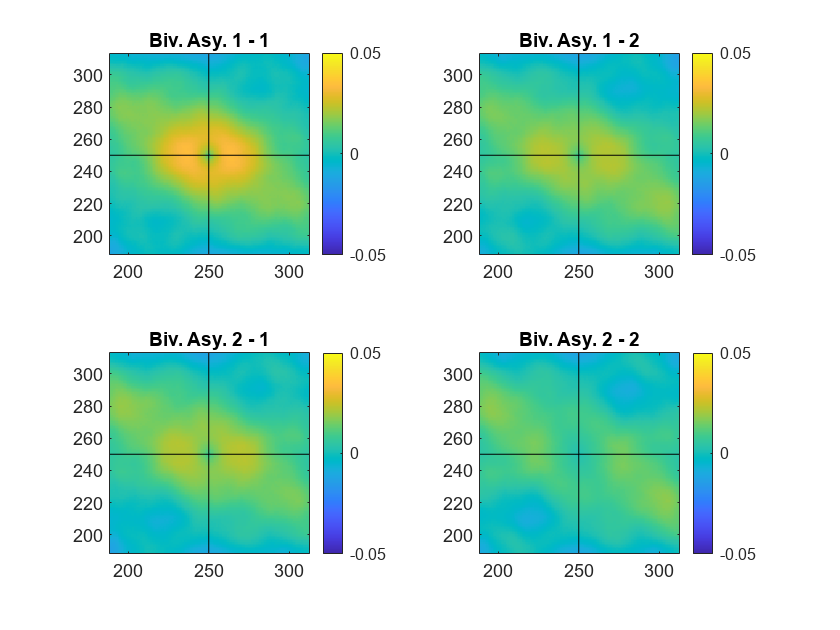

categ = 0; % Specify that the data is not categorical
display = 1; % Set display flag to true for visualization
rank = 1; % Set rank for GeoStatFFT
icode = 9; % Set code for rank asymmetry computation
figure(220)
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display, rank); % Compute bivariate asymmetry

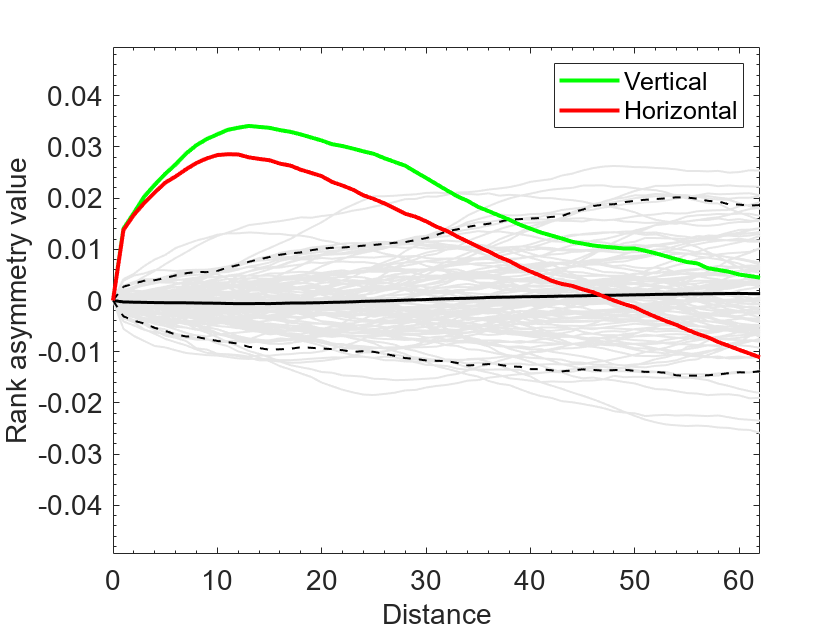


%% Simulation of Gaussian random fields for rank asymmetry
[z]=fftma([1 0 0 0 0 0 0 ; 2 50/3 50/3 50/3 0 0 0],[0.13 ; 0.87],45124241,100,nx,1,ny,1);
categ = 0; % Specify that the data is not categorical
display = 0; % Set display flag to true for visualization
rank = 1; % Set rank for GeoStatFFT
for i =1:100
    gh1{i} = GeoStatFFT(x0,z(:,i),icode, categ, display, rank);
end

% Plot the rank asymmetry results
figure(11)
for i = 1:100
    plot(0:length(gh1{i}{1,1}(nx:end, ny))-1, gh1{i}{1,1}(nx:end, ny), 'color', [0.9 0.9 0.9], 'LineWidth', 1) % Plot each realization
    hold on
    gmean(:, i) = gh1{i}{1,1}(nx:end, ny); % Store mean values for each realization
end
plot(0:length(mean(gmean, 2))-1, mean(gmean, 2), '-k', 'LineWidth', 1.5) % Plot mean
hold on
plot(0:length(quantile(gmean, 0.05, 2))-1, quantile(gmean, 0.05, 2), '--k', 'LineWidth', 1) % Plot 5th percentile
hold on
plot(0:length(quantile(gmean, 0.95, 2))-1, quantile(gmean, 0.95, 2), '--k', 'LineWidth', 1) % Plot 95th percentile
hold on
h1 = plot(0:length(gh{1,1}(nx:end, ny))-1, gh{1,1}(nx:end, ny), '-g', 'LineWidth', 2); % Plot vertical asymmetry
hold on
h2 = plot(0:length(gh{1,1}(nx, ny:end))-1, gh{1,1}(nx, ny:end), '-r', 'LineWidth', 2); % Plot horizontal asymmetry

% Add legend and labels
legend([h1 h2], {'Vertical', 'Horizontal'}) % Add legend
xlabel('Distance') % Label x-axis
ylabel('Rank asymmetry value') % Label y-axis

% Adjust font size and axis limits
fontsize(gca, 14, 'points'); % Adjust font size
xlim([0 floor(nx/4)]); % Set x-axis limits
ylim([-0.0495 0.0495]); % Set y-axis limits
set(gca, 'XMinorTick', 'on'); % Enable minor ticks on x-axis
set(gca, 'YMinorTick', 'on'); % Enable minor ticks on y-axis